clc;clear;close all;

## 1、生成点

% warning off
% 
% x = [-0.17263699	0.64102824	0.619187272	-0.169604585	-0.172290695	0.640753956	0.621242344	-0.170769907	-0.171522965	0.640246152	0.624506602	-0.171830944	-0.17083717	0.639008371	0.628110178	-0.171314854];
% y = [0.018979904	0.142571117	0.609214188	0.276047528	-0.053249894	-0.032656584	0.438329502	0.208959385	-0.125595109	-0.206542736	0.267949915	0.140160375	-0.198118165	-0.378594402	0.096932468	0.069163785];
% z = [-0.344388792	-0.670489171	0.286631526	0.1830114	-0.309268295	-0.580626074	0.372157833	0.220360057	-0.273244453	-0.491250982	0.458562455	0.258402244	-0.237311062	-0.402116506	0.545590665	0.294559421];
% 
% 
% azimuth = 5.819341;
% elevation = 1.582673;
% 
% P1 = [-0.25222006 0.655135248 -0.327650295];
% P2 = [-0.249753513 -0.390018781 0.195244076];
% 
% % xx = [-0.166541824	-0.143183482	0.086083038	0.156469149	0.466618822	0.56448817	0.839716947	0.807804096];
% % yy = [-0.049231542	0.233661612	-0.104236007	0.34170614	-0.091332629	0.380144412	0.261440943	0.017627278];
% % zz = [0.365326614	-0.524532874	0.659289339	-0.829545167	0.707237057	-0.813472591	-0.522760129	0.428110448];
% % PointFC = [xx;yy;zz];
% Points = [x;y;z];
% % Points = [Points,PointFC];
% 
% PAB = Points(:,5);



## 1、读取点

warning off
[num,txt,raw] = xlsread("2024_12_13.xlsx");
num(4:5,:)=[];

% num = [num(1:15,:);num(13:17,:);num(16:end,:)];
x = num(27,~isnan(num(27,:)));
y = num(29,~isnan(num(29,:)));
z = num(28,~isnan(num(28,:)));
azimuth = num(24,1);
elevation = num(24,2);
Points = [x;y;z];

PAB = num([19,21,20],2);
% PAB = Points(:,5);


P1 = num([50,52,51],2);
P2 = num([50,52,51],3);

num = 8;
laynum = 5;

load('PointIn.mat')
% 测试 生成 一个截面 测点
Point_out = generate_unit_circle_with_normal_vector2(PointIn,num,laynum,P1,P2);


## 拟合圆柱

% 测试 测点的拟合
[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Point_out,P1,P2);

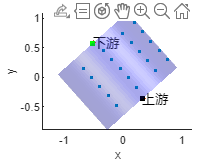


figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

%绘制散点
scatter3(Point_out(1,:),Point_out(2,:),Point_out(3,:),5,"filled");
scatter3([P1(1),P2(1)],[P1(2),P2(2)],[P1(3),P2(3)],10,"filled");






scatter3(Bottom_round_center1(1),Bottom_round_center1(2),Bottom_round_center1(3),20,'filled','black')
text(Bottom_round_center1(1),Bottom_round_center1(2),Bottom_round_center1(3),'上游')


scatter3(Bottom_round_center2(1),Bottom_round_center2(2),Bottom_round_center2(3),20,'filled','green')
text(Bottom_round_center2(1),Bottom_round_center2(2),Bottom_round_center2(3),'下游')